# Reeksamen 2015F

## Opgave 1

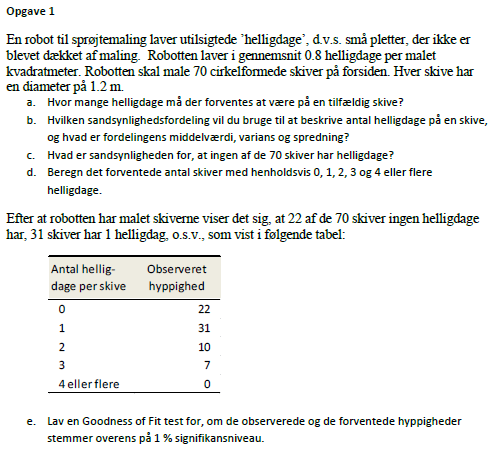'

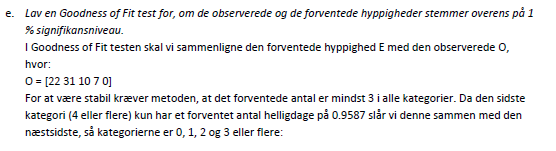

clc; clear;

lambda = 0.9048;
it = [22,31,10,7, 0];
hd = [0,1,2,3,4];

last = 1 - sum(poisspdf(hd(:, 1:end-1),lambda))

last = 0.0137


sshs = [poisspdf(hd(:, 1:end-1), lambda), last]

sshs =     0.4046    0.3661    0.1656    0.0500    0.0137





forv = sshs*70

forv =    28.3236   25.6272   11.5937    3.4967    0.9588


Formel for teststørrelsen


$${\chi_{0}}^{2}={\Sigma_{i}}^{k}\,\frac{{\left(O_{i}-E_{i}\right)}^{2}}{E_{i}}$$

-----------------------------------------------------------------
Antal frihedsgrader


$$\mathrm{dfs}=k-p-1$$

-----------------------------------------------------------------
Kritiske grænse - MATLAB kommando


$${\chi_{\alpha }}^{2}=\mathrm{chi2inv}\,\alpha \,\mathrm{dfs}$$

-----------------------------------------------------------------
    Signifikansniveau    Parametre    Frihedsgrader    Kritisk grænse    Teststørrelse
    _________________    _________    _____________    ______________    _____________

          "%1"               0              3              11.345           7.2261    



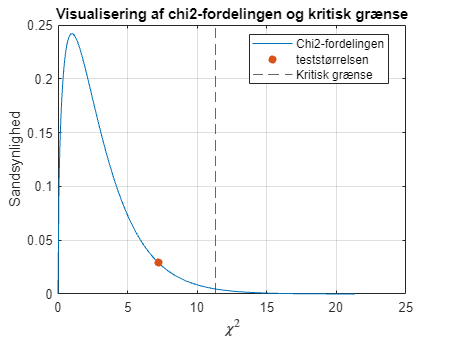


chi2normal(it, forv, 99, 0, 4)


chi2_0 = sum(((it - forv) .^ 2) ./ forv)

chi2_0 = 7.2261

Frihedsgradernes formel


$$\mathrm{df}=n_{1}+n_{2}-2$$

-----------------------------------------------------------------
Stikprøvemiddelværdiernes formel


$$\bar{y}=\frac{\Sigma \,y_{i}}{n}$$

-----------------------------------------------------------------
Stikprøvevariansernes formel


$$s=\frac{n\,\left(\Sigma \left({y_{i}}^{2}\right)-{\Sigma \left(y_{i}\right)}^{2}\right)}{n\,\left(n-1\right)}$$

-----------------------------------------------------------------
Pooled standardafvigelsens formel


$$s_{p}=\sqrt{\frac{\left(n_{1}-1\right)\,{s_{1}}^{2}+\left(n_{2}-1\right)\,{s_{2}}^{2}}{n_{1}+n_{2}-2}}$$

-----------------------------------------------------------------
t-værdiens formel


$$t_{\mathrm{df},\alpha }=-\mathrm{tinv}\,\alpha \,\mathrm{df}$$

-----------------------------------------------------------------
Teststørrelsens formel


$$t_{\mathrm{val}}=\frac{y_{\mathrm{bar1}}-y_{\mathrm{bar2}}-\delta }{s_{p}\,\sqrt{\frac{1}{n_{1}}\,\frac{1}{n_{2}}}}$$

-----------------------------------------------------------------
    Datanavne    Middelværdier    Spredning    standardafv.    Datapunkter
    _________    _____________    _________    ____________    ___________

        A              86          17.455         4.1779           12     
        B            81.2          24.178         4.9171           10     

    Frihedsgrader    Pooled varians    Pooled spredning    Teststatistik      t0      p-værdi    h-værdi
    _____________    ______________    ________________    _____________    ______    _______    _______

         20  

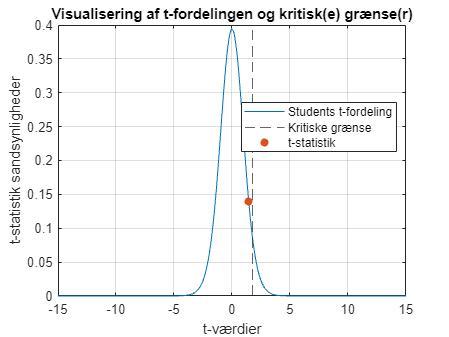

Da h = 0 forkastes nulhypotesen ikke
Ydermere ses det også at t-værdien 1.445 ikke overstiger den kritiske grænse på 1.7247


noget = struct with fields:
    stats: [1×1 struct]
        p: 0.9889
       ci: [-Inf 8.1420]



clc; clear;


A = [89 90 88 91 89 85 87 83 89 78 80 83];

B = [78 88 83 77 88 72 80 80 83 83];


noget = ttest2popMiddelInd(A, B, "left", 95, 2)

% t test med 2 stikprøver
% man er nødt til at antage de 2 populationer har samme standardafvigelse

ybar1 = mean(A)

ybar1 = 86

ybar2 = mean(B)

ybar2 = 81.2000


var1 = var(A)

var1 = 17.4545

var2 = var(B)

var2 = 24.1778


std1 = std(A)

std1 = 4.1779

std2 = std(B)

std2 = 4.9171


nn1 = length(A)

nn1 = 12

nn2 = length(B)

nn2 = 10



df = nn1 + nn2 - 2

df = 20



S = ((nn1 - 1)*var1 + (nn2 - 1)*var2)/df

S = 20.4800

sp = sqrt(S)

sp = 4.5255


H0 = 2

H0 = 2


tt = (ybar1 - ybar2 - H0)/(sp * sqrt(1/nn1 + 1/nn2))

tt = 1.4450



test_val = tinv(0.95, df)

test_val = 1.7247



xxs = linspace(-15, 15, 300);
pd = tpdf(xxs, df);

tvalpdf = tpdf(tt, df);

[h,p,ci,stats] = ttest2(A, B, "Tail", "right","Alpha", 0.95)

h = 1

p = 0.0111

ci =     8.1420       Inf


stats = struct with fields:
    tstat: 2.4772
       df: 20
       sd: 4.5255



ttt = (ybar1 - ybar2 - 0)/(sp * sqrt(1/nn1 + 1/nn2))

ttt = 2.4772

Frihedsgradernes formel


$$20=n_{1}+n_{2}-2$$

-----------------------------------------------------------------
Stikprøvemiddelværdiernes formel


$$\bar{y}=\frac{\Sigma \,y_{i}}{n}$$

-----------------------------------------------------------------
Stikprøvevariansernes formel


$$s=\frac{n\,\left(\Sigma \left({y_{i}}^{2}\right)-{\Sigma \left(y_{i}\right)}^{2}\right)}{n\,\left(n-1\right)}$$

-----------------------------------------------------------------
Pooled standardafvigelsens formel


$$s_{p}=\sqrt{\frac{\left(n_{1}-1\right)\,{s_{1}}^{2}+\left(n_{2}-1\right)\,{s_{2}}^{2}}{n_{1}+n_{2}-2}}$$

-----------------------------------------------------------------
t-værdiens formel


$$\frac{t_{\mathrm{df},\alpha }}{2}=-\mathrm{tinv}\,\frac{\alpha }{2}\,20$$

-----------------------------------------------------------------
Teststørrelsens formel


$$t_{\mathrm{val}}=\frac{y_{\mathrm{bar1}}-y_{\mathrm{bar2}}-\delta }{s_{p}\,\sqrt{\frac{1}{n_{1}}\,\frac{1}{n_{2}}}}$$

-----------------------------------------------------------------
    Datanavne    Middelværdier    Spredning    standardafv.    Datapunkter
    _________    _____________    _________    ____________    ___________

        A              86          17.455         4.1779           12     
        B            81.2          24.178         4.9171           10     

    Frihedsgrader    Pooled varians    Pooled spredning    Teststatistik     t0      p-værdi     h-værdi
    _____________    ______________    ________________    _____________    _____    ________    _______

         20  

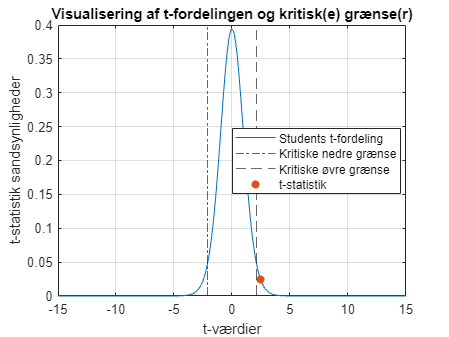

Da h = 1 forkastes nulhypotesen
Ydermere ses det også at t-værdien 2.4772 overstiger den kritiske grænse på 2.086


ans = struct with fields:
    stats: [1×1 struct]
        p: 0.0223
       ci: [0.1047 9.4953]



ttest2popMiddelInd(A, B, "both", 95, 0)

Stikprøvemiddelværdiens formel


$$\bar{y}=\frac{\Sigma \,y_{i}}{n}$$

-----------------------------------------------------------------
Stikprøvevariansens formel


$$s=\frac{n\,\left(\Sigma \left({y_{i}}^{2}\right)-{\Sigma \left(y_{i}\right)}^{2}\right)}{n\,\left(n-1\right)}$$

-----------------------------------------------------------------
Stikprøvestandardafvigelsens formel


$$s=\sqrt{\frac{n\,\left(\Sigma \left({y_{i}}^{2}\right)-{\Sigma \left(y_{i}\right)}^{2}\right)}{n\,\left(n-1\right)}}$$

-----------------------------------------------------------------
t-værdiens formel


$$t_{\mathrm{df},\alpha }=-\mathrm{tinv}\,\left(\alpha \,n-1\right)$$

-----------------------------------------------------------------
Teststørrelsens formel


$$t=\frac{\bar{y}-\mu_{0}}{s\,\sqrt{n}}$$

----------------------------------------------------------------------------------------------
    Datanavn    Middelværdi    Spredning    Standardafv.    Datapunkter
     navn                                                              
    ________    ___________    _________    ____________    ___________

     {'A'}         86.0         17.455         4.1779           12     

    Frihedsgrader    Teststatistik      t0      p-værdi     h-værdi
    _____________    _____________    ______    ________    _______

         11              -1.7         1.7959    0.062733       0   



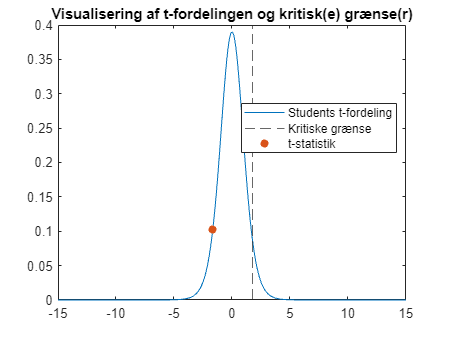

Da h = 0 forkastes nulhypotesen ikke
Ydermere ses det også at t-værdien -1.6583 ikke overstiger den kritiske grænse på 1.7959



StudentTestMiddel(A, 88, "left", 95)